% Read data from a text file
filename = 'test.txt';  % Replace with your actual filename
fileID = fopen(filename, 'r');

% Read the number of periods (n)
n = fscanf(fileID, '%d', 1);

% Initialize vectors for demand, set-up cost, production cost, and storage cost
d = zeros(1, n);
f = zeros(1, n);
p = zeros(1, n);
h = zeros(1, n);

% Read the rest of the data from the file
for i = 1:n
    data = fscanf(fileID, '%d %d %d %d', [1 4]);  % Read one line at a time
    d(i) = data(1);  % Demand
    f(i) = data(2);  % Set-up cost
    p(i) = data(3);  % Production cost
    h(i) = data(4);  % Storage cost
end

fclose(fileID);

% Now you can proceed to use the d, f, p, and h vectors in your graph construction
% Initialize the graph with n+1 vertices for the lot-sizing problem
V = n+1;  % Nodes are from 0 to n

edgeList = [];
weights = [];

% Construct the graph by adding arcs between all (i,j) where i < j
for i = 0:n-1
    for j = i+1:n
        if j == i+1
            % No storage cost if production is only for one period
            cost = f(i+1) + sum(p(i+1:j) .* d(i+1:j));
        else
            % Include storage costs for periods that hold inventory
            cost = f(i+1) + sum(p(i+1:j) .* d(i+1:j)) + sum(h(i+1:j-1) .* d(i+1:j-1));
        end
        edgeList = [edgeList; i+1, j+1];  % Add edge (i,j) -> node 0 is 1 in MATLAB
        weights = [weights; cost];
    end
end

% Create the graph and solve using Bellman-Ford from node 1
G = digraph(edgeList(:,1), edgeList(:,2), weights);
startVertex = 1;

% Run Bellman-Ford to find shortest path from 0 to n
[dist, pred] = BellmanFordPWSSSP(V, edgeList, weights, startVertex);

% Output the results
disp('Shortest Path Distances:');

Shortest Path Distances:


disp(dist);

     0
    14
    28
    48
    55



disp('Predecessor Nodes:');

Predecessor Nodes:


disp(pred);

     0
     1
     1
     3
     4



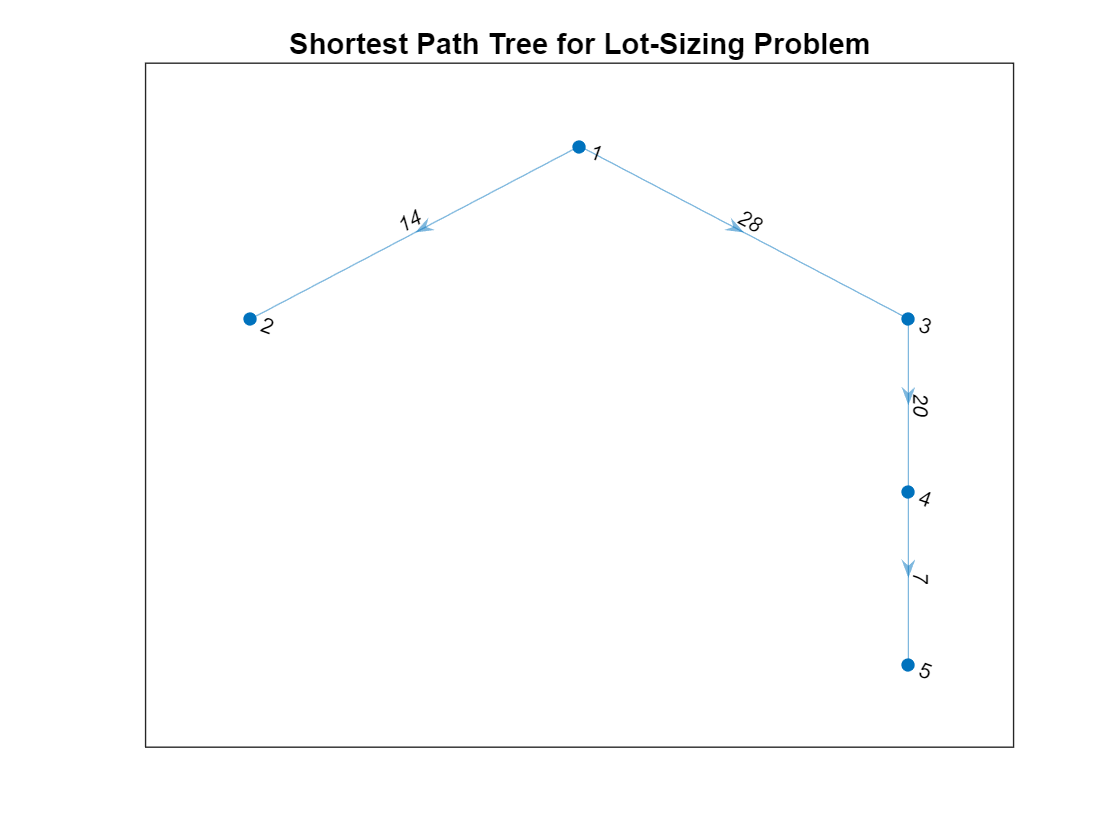


% Reconstruct the shortest path tree
treeEdges = [];
treeWeights = [];
for v = 1:V
    if pred(v) ~= 0  % If node has a predecessor
        treeEdges = [treeEdges; pred(v), v];
        idx = find(edgeList(:,1) == pred(v) & edgeList(:,2) == v);
        treeWeights = [treeWeights; weights(idx)];
    end
end

% Create and plot the shortest path tree
treeGraph = digraph(treeEdges(:,1), treeEdges(:,2), treeWeights);
plot(treeGraph, 'EdgeLabel', treeGraph.Edges.Weight);
title('Shortest Path Tree for Lot-Sizing Problem');


% Print the total minimal cost
totalCost = dist(V);  % The distance to the last node V gives the total cost
disp('Total minimal cost for the lot-sizing problem:');

Total minimal cost for the lot-sizing problem:


disp(totalCost);

    55





% Bellman-Ford Function from Lab2

function [dist, pred] = BellmanFordPWSSSP(V, edgeList, weights, s)
    % V: number of vertices
    % edgeList: edge list for the weighted graph
    % weights: weight array corresponding to the edges
    % s: source vertex
    
    % Initialize distance and predecessor arrays
    dist = ones(V, 1) * Inf;  % Initialize all distances as infinity
    pred = zeros(V, 1);       % Initialize predecessors as 0 (or -1 for unvisited nodes)
    
    dist(s) = 0;  % Distance from source to itself is 0
    
    % Bellman-Ford main algorithm loop
    for i = 1:V-1
        for j = 1:length(edgeList)
            u = edgeList(j, 1);
            v = edgeList(j, 2);
            w = weights(j);
            if dist(u) + w < dist(v)  % Relax the edge
                dist(v) = dist(u) + w;
                pred(v) = u;  % Record predecessor
            end
        end
    end
end
